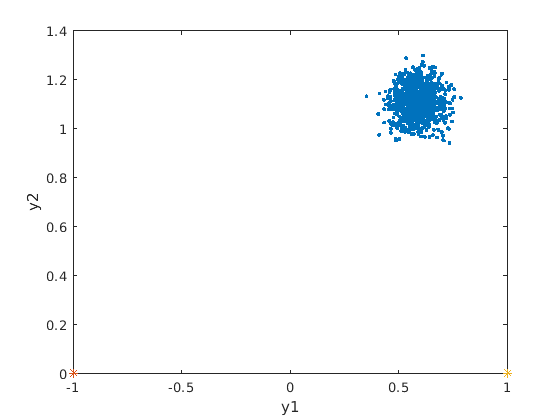

clear
X = zeros(2,1000)+[2;2];

s1 = [-1, 0]';
s2 = [1, 0]';
sigma_r=pi/50;
R=diag([sigma_r sigma_r]).^2;
m = size(R,1);
measModel = @(X) dualBearingMeasurement(X, s1, s2);
Y = genNonLinearMeasurementSequence(X, measModel, R);
figure(1),clf
plot(Y(1,:),Y(2,:),'.')
hold on
plot(s1(1),s1(2),'*')
plot(s2(1),s2(2),'*')
xlabel('y1');ylabel('y2');